# Validating the special property of linear systems

clear;clc;

dt = 0.01;
T = 10;
t = 0:dt:T-dt;

w = 1;
u = sin(w*t);
s = tf('s');
sys = 1/(s^2+5*s+4);
y = lsim(sys,u,t);
plot(t,y,'k');

## Analytic expression for output by substituting the transfer function

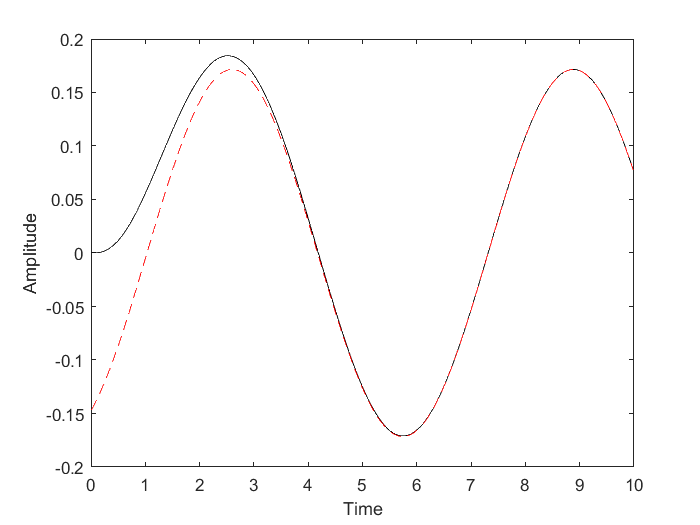

G = evalfr(sys,1i*w);
mag = abs(G);
phase = angle(G);

xt = mag*sin(w*t+phase);
hold on;
plot(t,xt,'r--');
xlabel('Time');
ylabel('Amplitude');

% Initial disagreement is maybe due to the fact that the output response
% matches with the real system response in terms of frequency and
% amplitude only after a few secs into the system response